# Широкоплосная частотная модуляция 

# Wide Band Frequency Modulation

# (WBFM)

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Введение

В FM Transitter Basics были рассмотрены оснывные принципы частотной модуляции и введены такие важные понятия как девиация и индекс модуляции. Было показано, что при больших индексах модуляции спектр сигнала множество новых частотных компонент, которых не было в исходном информационном сообщении. Такой случай называется широкополосной частотной модуляцией (Wide Band Frequency Modulation - WBFM). Рассмотрим WBFM подробнее.

### 2. Однотональная модуляция

Начнем с наиболее простого случая однотональной модуляции.Информационное сообщение представляет из себя гармонический сигнал вида: 

$m\left(t\right)=A_m \cos \left(2\pi f_m t\right)$,

где $A_m$ - амплитуда тона, $f_m$ - частота в герцах. 

Напомним, что в общем виде частотно-модулированный сигнал можно записать в виде:

 
$$s\left(t\right)=A_с \cdot \cos \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)\;\;\;\;\;\;\;\;\left(1\right),$$


где $A_с$ - амплитуда несущей, $f_с$ - частота несущей, $K_f$ - чувствительность модулятора.

Подставим это выражение в уравнение для однотонального сообщения в (3) и получим:


$$s\left(t\right)=A_с \cdot \cos \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t A_m \cos \left(2\pi f_m t\right)\cdot d\tau \right)\ldotp$$


После интегрирования получим:


$$s\left(t\right)=A_с \cdot \cos \left(2\pi f_с t+\frac{2\pi K_f A_m }{2\pi f_m }\cdot \sin \left(2\pi f_m t\right)\right)=A_с \cdot \cos \left(2\pi f_с t+\frac{K_f A_m }{f_m }\cdot \sin \left(2\pi f_m t\right)\right)=A_с \cdot \cos \left(2\pi f_с t+\beta \cdot \sin \left(2\pi f_m t\right)\right),$$


где $\beta =\frac{K_f A_m }{f_m }$ - индекс модуляции.

Применим к найденному уравнению формулу суммы углов для косинуса. Тогда модулированный сигнал примет вид:


$$s\left(t\right)=A_с \cdot \cos \left(2\pi f_с t+\beta \cdot \sin \left(2\pi f_m t\right)\right)=A_с \cdot \cos \left(2\pi f_с t\right)\cdot \cos \left(\beta \cdot \sin \left(2\pi f_m t\right)\right)-A_с \cdot \sin \left(2\pi f_с t\right)\cdot \sin \left(\beta \cdot \sin \left(2\pi f_m t\right)\right)\ldotp$$


При широкоплосной модуляции применять апроксимацию к для NBFM нельзя. Поэтому восспользуемся явным разложением функций $\cos \left(\beta \cdot \sin \left(2\pi f_m t\right)\right)$ и $\sin \left(\beta \cdot \sin \left(2\pi f_m t\right)\right)$ в ряд Тейлора:


$$\cos \left(\beta \cdot \sin \left(2\pi f_m t\right)\right)=J_0 \left(\beta \right)+2{\cdot J}_2 \left(\beta \right)\cdot \cos \left(2\cdot 2\pi f_m \cdot t\right)+2{\cdot J}_4 \left(\beta \right)\cdot \cos \left(4\cdot 2\pi f_m \cdot t\right)+\cdots ,$$



$$\sin \left(\beta \cdot \sin \left(2\pi f_m t\right)\right)=2{\cdot J}_1 \left(\beta \right)\cdot \sin \left(1\cdot 2\pi f_m \cdot t\right)+2{\cdot J}_3 \left(\beta \right)\cdot \sin \left(3\cdot 2\pi f_m \cdot t\right)+\cdots ,$$


где $J_n \left(\beta \right)$ - функция Бесселя первого рода $n$-ого порядка.

Подставим это разложение в уравнение для модулированного сигнала и получим:


$$s\left(t\right)=A_с \cdot \left\lbrack \cos \left(2\pi f_с t\right)\cdot \cos \left(\beta \cdot \sin \left(2\pi f_m t\right)\right)-\sin \left(2\pi f_с t\right)\cdot \sin \left(\beta \cdot \sin \left(2\pi f_m t\right)\right)\right\rbrack =$$



$$=A_с \cdot \left\lbrack \cos \left(2\pi f_с t\right)\cdot \left(J_0 \left(\beta \right)+2{\cdot J}_2 \left(\beta \right)\cdot \cos \left(2\cdot 2\pi f_m \cdot t\right)+2{\cdot J}_4 \left(\beta \right)\cdot \cos \left(4\cdot 2\pi f_m \cdot t\right)+\cdots \right)-\right.$$


$\left.-\;\sin \left(2\pi f_с t\right)\cdot \left(2{\cdot J}_1 \left(\beta \right)\cdot \sin \left(1\cdot 2\pi f_m \cdot t\right)+2{\cdot J}_3 \left(\beta \right)\cdot \sin \left(3\cdot 2\pi f_m \cdot t\right)+\cdots \right)\right\rbrack$.

Применим правила произведения синусов и косинусов и получим окончательный результат:


$$s\left(t\right)=A_с \cdot J_0 \left(\beta \right)\cdot \cos \left(2\pi f_с t\right)-A_с {\cdot J}_1 \left(\beta \right)\cdot \left\lbrack \cos \left(2\pi \left(f_с -f_m \right)t\right)-\cos \left(2\pi \left(f_с +f_m \right)t\right)\right\rbrack +$$



$$+A_с {\cdot J}_2 \left(\beta \right)\cdot \left\lbrack \cos \left(2\pi \left(f_с -2f_m \right)t\right)+\cos \left(2\pi \left(f_с +2f_m \right)t\right)\right\rbrack -A_с {\cdot J}_3 \left(\beta \right)\cdot \left\lbrack \cos \left(2\pi \left(f_с -3f_m \right)t\right)-\cos \left(2\pi \left(f_с +3f_m \right)t\right)\right\rbrack +\cdots \ldotp$$


Таким образом, модулированный сигнал после однотональной модуляции будет содержать множество гармоник, амплитуды которых задаются функциями Бесселя. Эти амплитуды, в свою очередь, зависят с помощью индекса модуляции $\beta$. То есть, изменяя индекс модуляции и можем существунно изменить спектральный состав модулированного сигнала. Для наглядности ниже представлены несколько графиков функций Бесселя младших порядков.

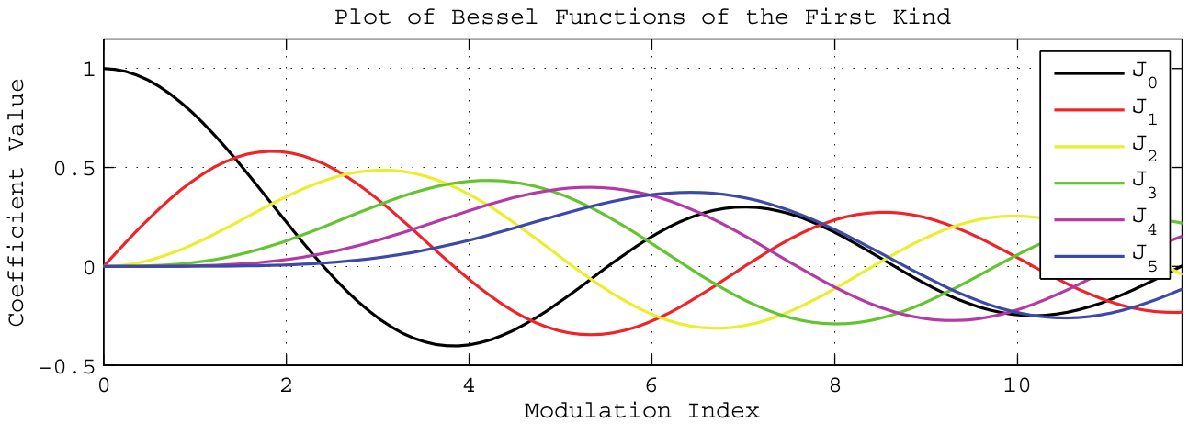

Можно увидеть, что с увеличением индекса модуляции функция нулевого порядка уменьшается. В сигнале эта функция соответствует амплитуде тона на частоте несущей, то есть, сначала амплитуда несущей будет уменьшаться. Функции других порядков сначала наоборот растут. Значит при увеличении индекса модуляции амплитуды гармоник в боковых полосах будут увеличивать. Это в свою очередь будет приводить к увеличению полосы сигнала. 

В таблице ниже представлены некоторые значения функций Бесселя при различном индексе модуляции. Если значение функции меньше 0.01, то в таблице ставится прочерк.

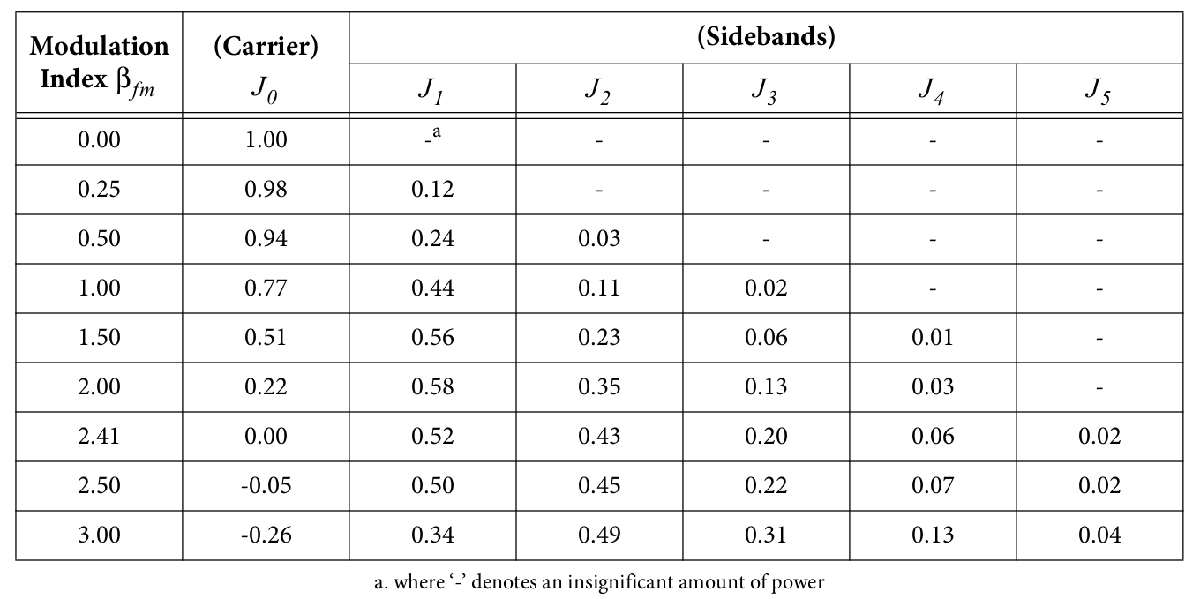

Можно увидеть, что при индексе модуляции меньше 0.5 в спектре будет содержаться всего две гармоники. Это соответствует результатам полученным ранее для узкополосной модуляции. При увеличении индекса модуляции все больше и больше гармоник будет преобретать существенную амплитуду.

Полосу частотно-модулированного сигнала можно приближенно оценить как

$\textrm{Band}=2\cdot n\cdot f_m$,

где $n$ - число гармоник имеющих существенную амплитуду.

Для однотональной модуляции число $n$ можно приближенно выразить через индекс модуляции в следующем виде:

$n=\beta +1$.

Отсюда для полосы сигнала можем получить еще одно уравнение:

$\textrm{Band}=2\cdot \left(\beta +1\right)\cdot f_m =2\cdot \left(\frac{\Delta f}{f_m }+1\right)\cdot f_m =2\cdot \left(\Delta f+f_m \right)$,

где - $\Delta f$ девиация.

Данное выражения называется формулой Карлсона (Carlson's Rule). Важно отметить, что все полученные результаты справедливы только для случая однотональной модуляции. Однако, на практике формулу Карлсона часто применяют для приближенной оценки полосы модулированного сигнала, даже если информационное сообщение имеет произвольную форму. При этом в качестве $f_m$ берется максимальная частота в спектре сообщения.

Убедимся в полученных результатах с помощью скрипта, реализующего однотональную частотную модуляцию и представленного ниже: 

clc; clear; close all;

FrameSize = 1011;                % размер обрабатываемой за один раз пачки данных
Fs = 100e3;                      % частота дискретизации (Hz)
Fc = 20e3;                       % частота несущей (Hz)
Am = 1;                          % амплитуда тонального сообщения
Fm = 2e3;                        % частота тонального сообщения (Hz)
ModIndex = 1;   % индекс модуляции

% вычисление чувствительности модулятора
Kf = ModIndex * Fm / Am;

% генератор однотонального сигнала
Message = dsp.SineWave(...
    'SampleRate',Fs,...
    'SamplesPerFrame',FrameSize,...
    'Frequency', Fm,...
    'Amplitude', Am ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm', ...
    'FrequencyRange', 'centered', ...
    'SampleRate', Fs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -Fs/2, ...
    'YLimits', [-15, 30], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'FM Signal'}, ...
    'SampleIncrement', Fs/FrameSize ...
    );

% начальная фаза интегратора
InitPhase = 0;

% запуск симуляции
for i = 1:100
    % формирование тонального сигнала
    MessageData = Message();

    % вычисление мгновенной частоты (Hz)
    freq = Fc + Kf * MessageData;
    
    % вычисление фазы в радианах c помощью интегрирования
    phase = InitPhase + 2*pi/Fs * cumsum(freq);
    
    % обновление начальной фазы интегратора
    InitPhase = phase(end);
    
    % формирование модулированного сигнала
    FmSignal = cos(phase);
    
    % вычисление спектров
    Spectrums = SpecEstimator([MessageData, FmSignal]);
    
    % вывод результатов на график
    Plotter(Spectrums)
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

Увеличиваю значение индекса модуляции $\beta$, можно увидеть появление новых гармоник, количество которых согласуется представленной выше таблицей. Таким образом, повторяя еще раз, спектр частотно-модулированного сигнала имеет достаточно сложную структуру и содержит спектральные составляющие, которых не было в исходном информационном сообщении. Ширина спектра зависит от индекса модуляции и ее приближенно можно оценить с помощью формулы Карлсона.

### 3. Модуляция аудиосигналом

Рассмотрим, как будет выглядеть спектр сигнала при широкополосной модуляции, если информационное сообщение является аудиосигналом. В файле Audio_Source.wav записано звуковое сообщение с частотой дискретизации $f_s =44\ldotp 1$ kHz. Частота несущей будет равна 100 kHz. Чтобы избежать наложения спектров, выберем итоговую частоту дискретизации модулированного сигнала в 10 раз больше частоты аудиосигнала, то есть 10 * 44.1 kHz. Это потребует провести интерполяцию для увеличения частоты дискретизации информационного сообщения.

Максимальное значение отсчетов данного конкретного аудиосигнала равно единице, то есть $\max \left|m\left(t\right)\right|=1\ldotp$ Также будем считать, что максимальная частота в спектре сообшения равна половине частоты дискретизации:

$f_m =\frac{f_s }{2}=22\ldotp 05\;\textrm{kHz}$.

Отсуда, индекс модуляции можно записать в виде:

 
$$\beta =\frac{K_f \cdot \max \left|m\left(t\right)\right|}{f_m }=2\cdot \frac{K_f }{f_s },$$


где $N$- число гармоник. 

Тогда чувствиельность модулятора можно представить в виде:

 
$$K_f =\frac{\beta \cdot f_s }{2}\ldotp$$


В соответствии с формулой Карлсона полосу сигнала можно приближенно оценить как:


$$\textrm{Band}=2\cdot \left(\beta +1\right)\cdot f_m =44\ldotp 1\cdot \left(\beta +1\right)\;\textrm{kHz}\ldotp$$


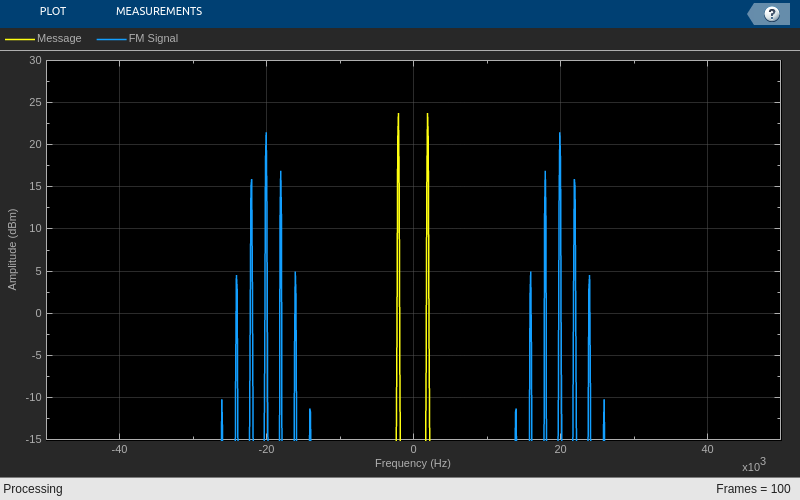

clc; clear; close all;

AudioFrameSize = 1000;           % количество отсчетов аудиофайла, получаемых за один раз
FramesNumber = 300;              % число обрабатываемых пачек данных
RateRatio = 10;                  % коэффициент увеличения частоты дискретизации
Fc = 100e3;                      % частота несущей (Hz)
ModIndex = 1;   % индекс модуляции

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_Source.wav', ...
    'SamplesPerFrame',AudioFrameSize...
    );

% дополнительные расчеты
AudioFs = AudioReader.SampleRate;               % получаем частоту дискретизации аудиосообщения
SignalFs = AudioFs * RateRatio;                 % частота дискретизации модулированного сигнала
SignalFrameSize = AudioFrameSize * RateRatio;   % количество отсчетов Ам-сигнала, получаемых за один раз

% вычисление чувствительности модулятора
Kf = ModIndex * AudioFs / 2;

% интерполятор 
Upsampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate',AudioFs, ...
    'OutputSampleRate', SignalFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...

    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'FM Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

% начальная фаза интегратора
InitPhase = 0;

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов аудиосообщения и выделение одного канала из
    % стерео сигнала
    AudioData = AudioReader();
    AudioData = AudioData(:,1);
    
    % увеличение частоты дискретизации аудиосообщения
    MessageData = Upsampler(AudioData);

    % вычисление мгновенной частоты (Hz)
    freq = Fc + Kf * MessageData;
    
    % вычисление фазы в радианах c помощью интегрирования
    phase = InitPhase + 2*pi/SignalFs * cumsum(freq);
    
    % обновление начальной фазы интегратора
    InitPhase = phase(end);
    
    % формирование модулированного сигнала
    FmSignal = cos(phase);

    % вычисление спектров
    SpectrumData = SpecEstimator([MessageData, FmSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.05)
end

Можно увидеть, что при увеличении индекса модуляции ширина спектра увеличивается. Формула Карлсона дает неплохую приближенную оценку полосы сигнала. Например, при индексе модуляции равном единице полоса сигнала примерно вдвое больше полосы сообщения. 

### 4. Непрямой метод широкополосной модуляции

Рассмотрим еще один способ реализации широкополосного частотного модулятора с помощью метода, который называется непрямым методом Армстронга. Его идея заключается в формировании узкополосного модулированного сигнала с помощью схемы рассмотренной в FM Transmitter NBFM, и далее увеличении индекса модуляции с помощью частотного умножителя. Частотный умножитель представляет из себя любое нелинейное устройство, за которым следует полосовой фильтр. 

Схема модулятора будет иметь вид:

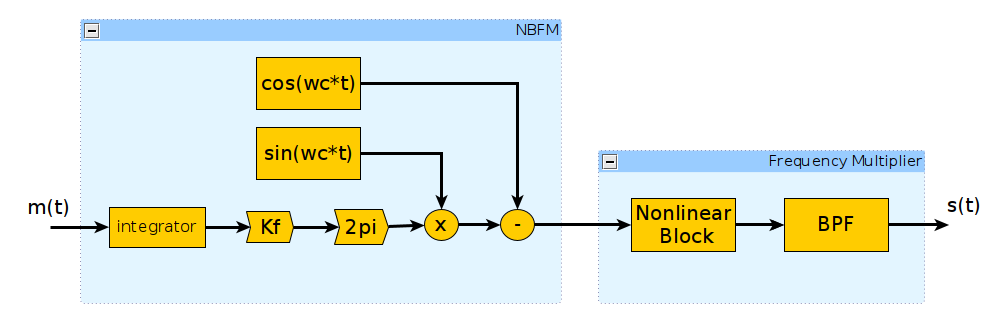

Рассмотрим принцип его действия более подробно на примере квадратичной нелинейности. 

Для квадратичной нелинейности входной $x\left(t\right)$ и выходной $y\left(t\right)$ сигналы связаны следующим образом: 

$y\left(t\right)=x^2 \left(t\right)$.

Подставим вместо $x\left(t\right)$ частотно-модулированный сигнал, применим правило умножения косинусов и получим:


$$y\left(t\right)={\left\lbrack A_с \cdot \cos \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)\right\rbrack }^2 ={A_с }^2 \cdot \left\lbrack \cos \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)\cdot \cos \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)\right\rbrack =$$



$$={A_с }^2 \cdot \left\lbrack 0\ldotp 5+0\ldotp 5\cdot \cos \left(2\pi \cdot 2f_с \cdot t+2\pi \cdot 2K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)\right\rbrack \ldotp$$


Таким образом, после возведения в квадрат получим сигнал, который состоит из постоянной составляющей и частотно-модулированного сигнала, несущая частота и чувствительность модулятора которого увеличина в двое. Так как чувствительность модулятора прямо пропорциональна девиации, то девиация также увиличится в двое. Далее с помощью полосового фильтра можно убрать постоянную составляющую и получить окончательный результат:


$$s\left(t\right)=0\ldotp 5\cdot {A_с }^2 \cdot \cos \left(2\pi \cdot 2f_с \cdot t+2\pi \cdot 2K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)\ldotp$$


При использовании нелинейности n-ого порядка и правильного выбранного полосового фильтра можно получить сигнал, девиация которого увеличина в n раз по сравнению с исходным NBFM сигналом. Одновременно с увеличиненем девиации, также в n раз будет увеличина частота несущей.

Рассмотрим данный метод для случая однотональной модуляции и квадратичной нелинейности. Пусть частота несущей исходного NBFM сигнала равна 10 кГц, а индекса модуляции равен 0.5. После применения частотного умножитель несущая частота будет равна 20 кГц, а индекс модуляции станет равен 1. Для удаления постоянной составляющей воспользуемся фильтром верхних частот.

Скрипт, реализующий непрямой метод Армстронга, представлен ниже:

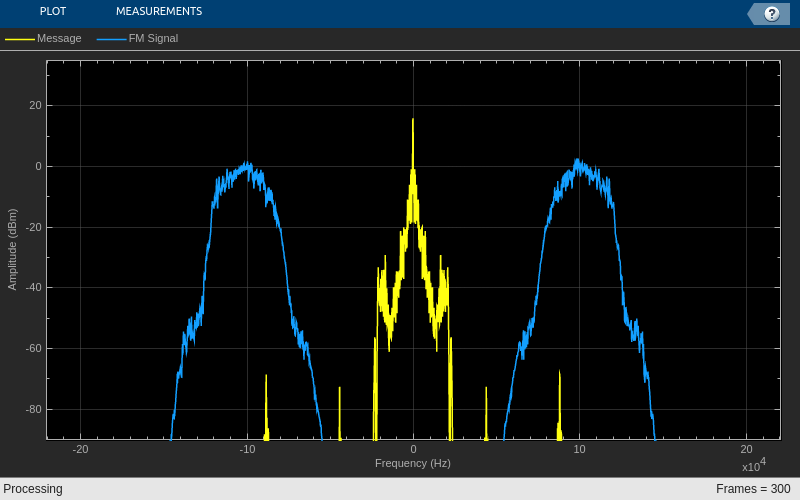

clc; clear; close all;
addpath('matlab/modulation');

FrameSize = 1011;       % размер обрабатываемой за один раз пачки данных
Fs = 100e3;             % частота дискретизации (Hz)
Fc = 10e3;              % частота несущей (Hz)
Am = 1;                 % амплитуда тонального сообщения
Fm = 2e3;               % частота тонального сообщения (Hz)
ModIndex = 0.5;         % индекс модуляции

% вычисление чувствительности модулятора
Kf = ModIndex * Fm / Am;

% генератор однотонального сигнала
Message = dsp.SineWave(...
    'SampleRate',Fs,...
    'SamplesPerFrame',FrameSize,...
    'Frequency', Fm,...
    'Amplitude', Am ...
    );

% генератор несущей
Carrier = dsp.SineWave(...
    'SampleRate',Fs,...
    'SamplesPerFrame',FrameSize,...
    'Frequency', [Fc Fc],...
    'Amplitude', [1 1], ...
    'PhaseOffset', [0 pi/2] ...
    );

% расчет коэффициентов фильтра верхних частота
H = Armstrong_Highpass_Filter(); 
HighpassFIR = dsp.FIRFilter(H.Numerator);

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm', ...
    'FrequencyRange', 'centered', ...
    'SampleRate', Fs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -Fs/2, ...
    'YLimits', [-15, 30], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'NBFM Signal', 'WBFM Signal'}, ...
    'SampleIncrement', Fs/FrameSize ...

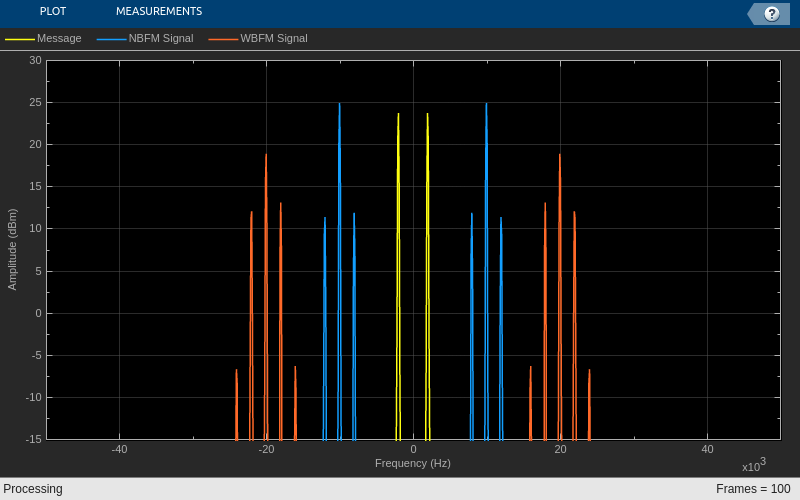

    );

% начальное значение интегратора
AccumInitValue = 0;

% запуск симуляции
for i = 1:100
    % формирование тонального сигнала
    MessageData = Message();

    % интегрирование сообщения
    MessageIntegral = AccumInitValue + 1/Fs * cumsum(MessageData);
    
    % обновление начального значения интегратора
    AccumInitValue = MessageIntegral(end);

    % получание несущей
    CarrierWave = Carrier();
    SinWave = CarrierWave(:,1);
    CosWave = CarrierWave(:,2);

    % умножение на несущую и добавление несущей сдвинутой по фазу
    NbFmSignal = CosWave - 2*pi*Kf * SinWave.*MessageIntegral; 
    
    % частотный умножитель
    WbFmSignal = HighpassFIR(NbFmSignal.^2);

    % вычисление спектров
    Spectrums = SpecEstimator([MessageData, NbFmSignal, WbFmSignal]);
    
    % вывод результатов на график
    Plotter(Spectrums)
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

На спектрограмме желтым цветом представлен исходное однотональное сообщение. Синим цвет обозначен сигнал после узкополосной частотной модуляции. Красным светом показан сигнал после частотного умножителя. Можно увидеть, что его частота несущей и полоса вдвое больше чем у исходного NBFM сигнала.

Стоит отметить, что непрямой метод Армстронга имеет смысл применть, только если сигнал формируется аналоговыми методами. Если частото-модулированный сигнал получается цифровыми методами, например с помощью SDR, то лучше применть более простой прямой метод модуляции с помощью VCO.

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR